## Calcium Analysis

**Clear the workspace**

clear all
clc

Import excel spreadsheet from NIS Elements with data, in the following format: 

Frame    Cell 1    Cell 2    Etc

1            Value    Value    Value

2            Value    Value    Value

File = uigetfile('*.xlsx');
[Pre_data, Pre_headers] = xlsread(File);
Pre_headers = Pre_headers(2,:);
Data = Pre_data(:,3:end-1);
Data_headers = Pre_headers(1, 3:end-1);
Frame_column = Pre_data(:,1);
Frame_header = Pre_headers(1,1);
Time_column = Pre_data(:,2);
Time_header = Pre_headers(1,2);
[NumberofRows, NumberofColumns] = size(Data);
Max_value = max(max(Data));
Pre_time = datestr(Time_column, 'MM:SS:FFF');
Time = cellstr(Pre_time);

**Select cell type and treatment**

Cell_type = questdlg('What is the cell type?', 'Cell type', 'Neuron', 'Astrocyte', 'Cancel', 'Cancel');
Cell_type = cellstr(Cell_type);

Treatment = questdlg('What is the treatment?', 'Treatment', 'Baseline', 'KA', 'Cancel', 'Cancel');
Treatment = cellstr(Treatment);

Specifications = inputdlg({'What is the Short ID?', 'What is the Slice?', 'What is the genotype?', 'What is the age?', 'What is the full Animal ID?'}, 'Specifications');


**Plot Raw Data**

Figure1 = figure;
plot(Frame_column, Data)
axis([0 NumberofRows 0 Max_value+10])
title('Raw signal')
legend(Data_headers, 'Location', 'eastoutside')
ylabel('Intensity')
xlabel('Frame')

**Plot Individual Signal**

%Find out number dimension of figure for subplots
% according to how many columns there are, by
% finding the square root of the # of columns,
% approximated by ceil function

Dimensionofsubplots = ceil(sqrt(NumberofColumns));
Figure2 = figure;
for i = 1:NumberofColumns
    subplot1 = subplot(Dimensionofsubplots, Dimensionofsubplots, i);
    plot(Data(:,i));
    
    %plot specifications
    Max_value_subplot = max(max(Data(:,i)));
    axis([0 NumberofRows 0 Max_value_subplot+30]);
    title(Data_headers(i));
    xlabel('Frame');
    ylabel('Intensity', 'FontSize', 8)
end

**Calculate the overall mean**

Figure3 = figure;
OverallMeans = mean(Data);
bar(OverallMeans);

%plot specifications
title('Average of Gray Value');
xlabel('Cell #');
ylabel('Intensity');

**Calculate the moving average of previous 10 frames **

Mean = movmean(Data, [9 0]);
MeanPrevious10 = Mean(10:end, :);

%plot specifications
plot(Frame_column(10:end), MeanPrevious10)
[NumberofRows2, NumberofColumns2] = size(MeanPrevious10);
axis([10 NumberofRows2 0 max(max(MeanPrevious10))+10])
title('Moving average (10 previous frames)');
xlabel('Frame');
ylabel('Average');

## **Calculate dF/F (normalized data)**

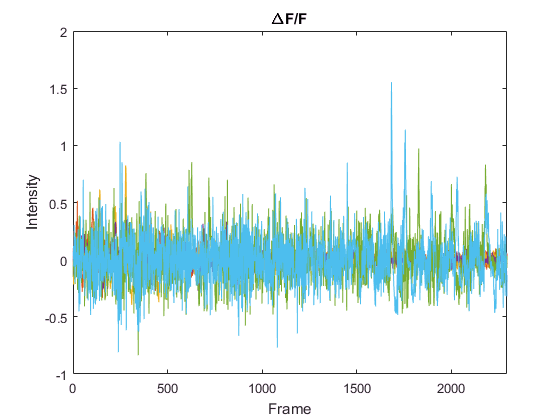

Datafrom10toEnd = Data(10:end, :);
DeltaFoverF = (Datafrom10toEnd - MeanPrevious10)./MeanPrevious10;

%For divisions by Zero, Matlab returns NaN. The following line shows an error if there is NaN.
for i = 1:NumberofColumns
    for j = 1:NumberofRows2
        if isnan(DeltaFoverF(j,i))
           error('Delta F cannot be 0')
        end
    end
end

Frame_column = Frame_column(10:end);
%plot with both positive and negative values
plot(DeltaFoverF)

%plot specifications
[NumberofRows4, NumberofColumns4] = size(DeltaFoverF);
axis([0 NumberofRows4 ylim])
title('\DeltaF/F');
xlabel('Frame');
ylabel('Intensity');

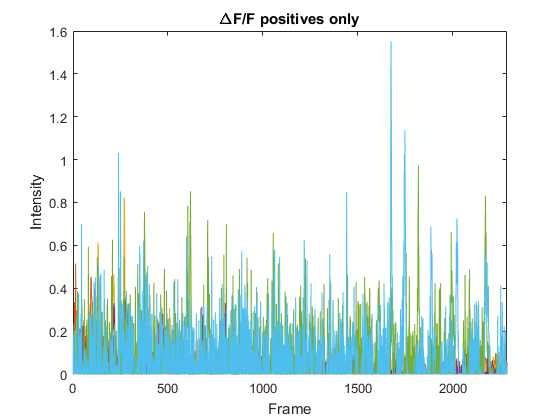


%Delta F with positive values only, negative values transformed in 0

DeltaFpositivesonly = DeltaFoverF;
DeltaFpositivesonly(DeltaFpositivesonly<0) = 0;
DeltaFpositivesonly = DeltaFpositivesonly(10:end,:);
plot(DeltaFpositivesonly)

%plot specifications
[NumberofRows4, NumberofColumns4] = size(DeltaFpositivesonly);
axis([0 NumberofRows4 ylim])
title('\DeltaF/F positives only');
xlabel('Frame');
ylabel('Intensity');

**Calculate the standard deviation of ****previous 10 frames**

StdDev = movstd(DeltaFoverF, [9 0]);
StandardDeviationPrevious10 = StdDev(10:end, :);
StandardDeviation = 2.5 .* StandardDeviationPrevious10;               % Creates array with values of 2.5*STD of 10 previous frames

## Find peaks and their features

% Creates matrix with values of DealtaF/F bigger than 2.5x StDev of 10 previous frames, otherwise, Zeros
DeltaFoverF = DeltaFoverF(10:end, :);
[NumberofRows5, NumberofColumns5] = size(DeltaFoverF);
Frame_column = Frame_column(10:end);

for i = 1:NumberofColumns5
    for j = 1:NumberofRows5
        if DeltaFoverF(j,i) >= StandardDeviation(j,i);
        Peakarray(j,i) = DeltaFoverF(j,i);
        else 
            Peakarray(j,i) = 0;
        end
    end
end


% Findpeaks in the matrix above
for i = 1:NumberofColumns5
    [Peakamplitude{i}, Peaklocation{i}, Peakwidth{i}, Peakprominence{i}] = findpeaks(Peakarray(:,i), Frame_column, 'MinPeakHeight', 0);
end

Error using findpeaks (line 134)
input vectors X and Y should have the same size.


%Example in graph of original signal and clean signal
    % Original = DeltaFpositives only
    % Clean = Peakarray values
plot(Frame_column, DeltaFpositivesonly(:,1))
plot(Frame_column, Peakarray(:,1))


**Display the clean signal (onl****y with 'valid' spikes) of each cell**

%Plot all cells' clean signal
[NumberofRows6, NumberofColumns6] = size(Peakarray);
Dimensionofsubplots = ceil(sqrt(NumberofColumns6));
Figure4 = figure;
for i = 1:NumberofColumns6
    subplot2 = subplot(Dimensionofsubplots, Dimensionofsubplots, i);
    plot(Peakarray(:,i));
    
    %plot specifications
    Max_value_subplot = max(max(Peakarray(:,i)));
    axis([0 NumberofRows6 0 Max_value_subplot]);
    title(Data_headers(i));
    xlabel('Frame');
    ylabel('Intensity', 'FontSize', 8)
end

**Average of Peaks amplitudes**

%Average of peaks amplitudes
for i = 1:NumberofColumns5
    AvgofPeaksAmplitudes{i} = mean(Peakamplitude{1,i});
end

%Transform cell array with averages into matlab array
AvgofPeaksAmplitudes = cell2mat(AvgofPeaksAmplitudes);

## Frequency of spikes

Duration = duration(00,05,00);

for i = 1:NumberofColumns5
    Frequency{i} = length(Peaklocation{1,i})/5;
end

Frequency = cell2mat(Frequency);
Frequency = Frequency';

**Write results to Excel file**

%Write results into a table
Cell_ID = Data_headers';
Genotype = repmat(Specifications(3,1), [length(Cell_ID), 1]);
Age = repmat(Specifications(4,1), [length(Cell_ID), 1]);
Short_ID = repmat(Specifications(1,1), [length(Cell_ID), 1]);
Animal_ID = repmat(Specifications(5,1), [length(Cell_ID), 1]);
Slice = repmat(Specifications(2,1), [length(Cell_ID), 1]);
Cell_type = repmat(Cell_type, [length(Cell_ID), 1]);
Treatment = repmat(Treatment, [length(Cell_ID), 1]);
Average_of_Spikes_Amplitudes = AvgofPeaksAmplitudes';
Frequency_of_Spikes = Frequency';

Table = table(Genotype, Age, Short_ID, Slice, Animal_ID, Cell_ID, Cell_type, Treatment, Average_of_Spikes_Amplitudes, Frequency)

%Write table to Excel file
filename = uiputfile('*.xlsx', 'Save to Excel');
writetable(Table, filename)